clear variables; close all; clc;

**Assignment:**

Try building HMMs with different numbers of states on this sequence.  Which number of states works best?  Explain your best model, interpreting the states (explain how they are different from each other, no biological interpretation needed).  

Corona2 = getgenbank('NC_045512');
N = Corona2.Sequence(28274:29533);
clear Corona2;
length_N = length(N); 

## Select number of States

note: 

- num_states must be even and >= 2 (must also be <=10 for speed reasons and actually wouldn't make much sense to have more with this example)

With a bit more patience and time one could simply extend the reasoning to odd numbers as well, implementation-wise it would be easy but some pain testing it.

### CHANGING THE SLIDER VALUE WILL LET THE CODE RUN AGAIN WITH NEW SELECTED PARAMETER


num_states = 4

num_states = 4

## Estimate Emission Matrix

select even number of states, so that one half will be indicating the frequency range, and the other half the respective symmetrical frequency, e.g.: 

4 states -> cg threshold range = [0.45 0.55] -> 

state 1 = cg threshold > 0.45 - state 3 = cg threshold < 0.45

state 2 = cg threshold > 0.55 - state 4 = cg threshold < 0.55

cgt = 0.4500

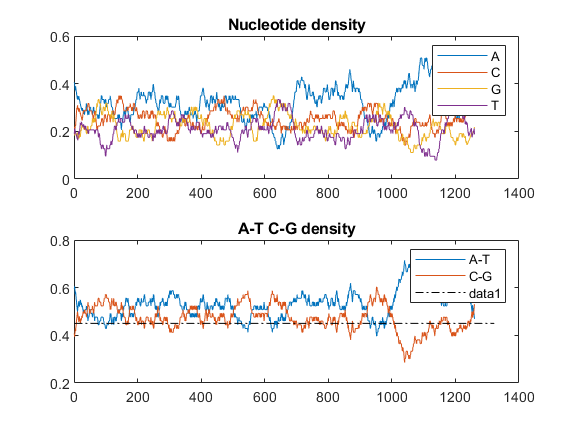

cgt = 0.5500

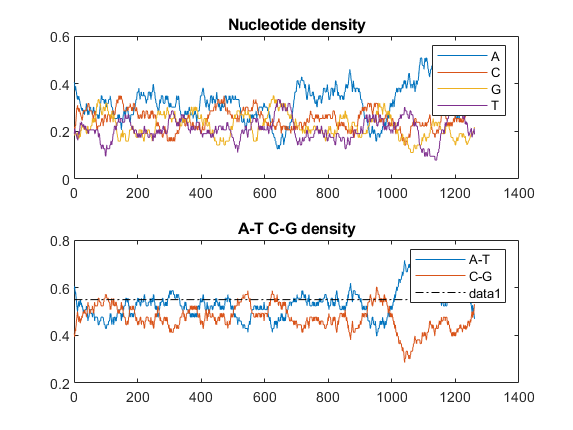

min = 0.45;  max = 0.55;                     % designed specifically for this case
mid = num_states/2;                          % num_states needs to be even so that reflects symmetry    
if mid==1; cgt_range= 0.5; else
cgt_range = linspace(min,max,mid); end       % initialise cg threshold range

E_guess = zeros(num_states,4);               % initialise E guess (num_states x num_bases)

for i = 1:mid                                % loop num_states/2 times
    cgt = cgt_range(i)                       % select cg threshold
    figure
    [d, hcg] = ntdensity(N,'CGTHRESHOLD',cgt);      % gather density indexes
    lcg = setdiff(1:length_N,hcg);                  % set difference with hcg 
            % hcg are now the indexes where CG bases appear with frequency
            % above cgt, hence the i(th) state
            % now we want to find the symmetric part
            % where CG bases appear with frequency                          
            % below cgt, hence the i+mid(th) state
    hn = string(N(hcg)); lhn = length(hcg);         % convert to strings gather lengths
    ln = string(N(lcg)); lln = length(lcg);
            % now for each base we count, in the sets 
            % we have just computed, the frequency of 
            % their appearences, and store them in a 
            % row array. Note: sum(c1) = sum(c2) = 1,
            % hence the model satisfies probability laws
    c1 = [count(hn,'a'), count(hn,'c'), count(hn,'g'), count(hn,'t')] ./ lhn;
    c2 = [count(ln,'a'), count(ln,'c'), count(ln,'g'), count(ln,'t')] ./ lln;
    E_guess(i,:) = c1;                              % store i^th state in E
    E_guess(mid+i,:) = c2;                          % store i+mid^th state in E
end

## Estimate Transition Matrix

Now generate basic Transition matrix with probability P = 80% of staying in the same state, and the remaining 25% will be evenly split between the states left,

hence generate matrix with P along its diagonal 

p_stay = 0.8;                      % probability of not changing state
p_switch = 0.2 / (num_states-1);   % probability of changing state
T_guess = zeros(num_states,num_states);   % initialise T
for i=1:num_states
    for k = 1:num_states            
        if i==k                     % diagonal line
            T_guess(i,k) = p_stay;        % 0.75
        else 
            T_guess(i,k) = p_switch;      % 0.25 / (states-1)
        end
    end
end

## Train HMM

Now we want to train the model by giving transition and emission matrices guesses.

E_guess, T_guess                                    % check what are we starting with

E_guess =     0.2921    0.2640    0.2360    0.2079
    0.1980    0.2574    0.3366    0.2079
    0.3713    0.2203    0.1931    0.2153
    0.3279    0.2494    0.2123    0.2105


T_guess =     0.8000    0.0667    0.0667    0.0667
    0.0667    0.8000    0.0667    0.0667
    0.0667    0.0667    0.8000    0.0667
    0.0667    0.0667    0.0667    0.8000


int_seq = nt2int(N);                                % convert to int sequence
[T_est, E_est] = hmmtrain(int_seq,T_guess,E_guess, ...
    Maxiterations=5e4)                              % train model with 5000 iterations

T_est =     0.0006    0.0000    0.5501    0.4492
    0.3054    0.6511    0.0000    0.0435
    0.2838    0.3705    0.3457    0.0000
    0.0000    0.1423    0.3136    0.5441


E_est =     0.0000    0.5107    0.4893    0.0000
    0.0000    0.2330    0.3780    0.3890
    0.9009    0.0000    0.0000    0.0991
    0.4214    0.3556    0.0000    0.2230


states_est = hmmviterbi(int_seq, T_est, E_est);     % generate likely states from trained model and given original sequence
[seq_gen, states_gen] = hmmgenerate(length_N, ...
    T_est,E_est,Symbols={'a','c','g','t'})          % generate likely sequence and likely states from trained model only

seq_gen = 1×1260 cell array
  Columns 1 through 1111

    {'a'}    {'a'}    {'c'}    {'a'}    {'a'}    {'a'}    {'g'}    {'c'}    {'a'}    {'g'}    {'t'}    {'g'}    {'c'}    {'a'}    {'c'}    {'g'}    {'t'}    {'a'}    {'a'}    {'c'}    {'c'}    {'c'}    {'a'}    {'a'}    {'g'}    {'c'}    {'a'}    {'c'}    {'c'}    {'a'}    {'a'}    {'a'}    {'c'}    {'c'}    {'a'}    {'a'}    {'c'}    {'c'}    {'c'}    {'a'}    {'c'}    {'a'}    {'c'}    {'a'}    {'a'}    {'c'}    {'a'}    {'t'}    {'g'}    {'c'}    {'a'}    {'a'}    {'t'}    {'g'}    {'g'}    {'t'}    {'t'}    {'g'}    {'a'}    {'a'}    {'c'}    {'a'}    {'a'}    {'g'}    {'t'}    {'t'}    {'g'}    {'c'}    {'g'}    {'t'}    {'c'}    {'c'}    {'c'}    {'t'}    {'c'}    {'a'}    {'t'}    {'c'}    {'a'}    {'g'}    {'c'}    {'t'}    {'g'}    {'a'}    {'t'}    {'g'}    {'a'}    {'g'}    {'t'}    {'c'}    {'g'}    {'a'}    {'c'}    {'a'}    {'a'}    {'a'}    {'t'}    {'g'}    {'t'}    {'t'}    {'c'}    {'a'}    {'a'}    {'g'}    {'a'} 

states_gen =      4     4     4     3     3     3     2     1     3     1     3     1     4     3     2     2     4     4     3     2     1     4     4     3     2     1     3     1     4     4     3     3     1     4     4     4     2     2     1     3     1     3     1     4     4     4     4     3     2     1


seq_gen = cell2mat(seq_gen);                        % convert to array

## Analyse results

Now we sort the two states-sequences generated to compare them and gather equality ratio

the more likely the two sequences appear to be the more efficient the model would be ideally?

Of course one would have to iterate this comparison many times to estimate it realistically.

accuracy = sum(sort(states_est) == sort(states_gen)) / length_N

accuracy = 0.7563

## Display results

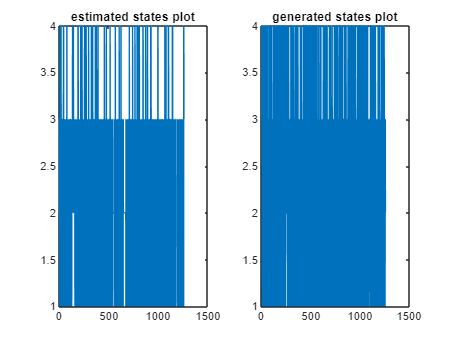

figure;
subplot(1,2,1); plot((1:length_N),states_est); title("estimated states plot");
subplot(1,2,2); plot((1:length_N),states_gen); title("generated states plot");

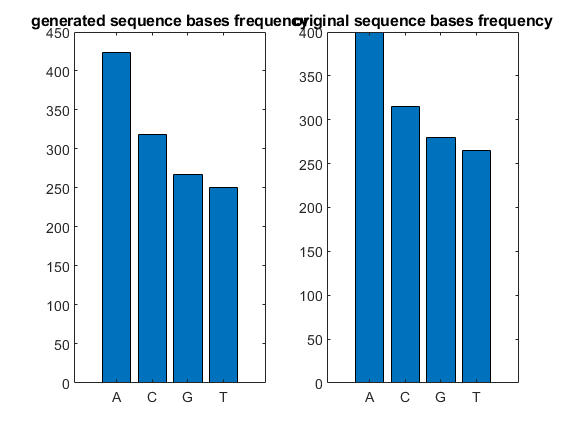

% figure; ntdensity(seq_gen,'Window',length_N/9); title("HMM Trained")
% figure; ntdensity(N,'Window',length_N/9); title("Original Sequence")
figure;
subplot(1,2,1); basecount(seq_gen,'CHART', 'bar'); title("generated sequence bases frequency")
subplot(1,2,2); basecount(N,'CHART','bar'); title("original sequence bases frequency")

## Conclusions

In my idea one could use this idea with some improvements to analytically determine the dimensions of the model after some testing. Of course there is a lot of room for further implementations/improvements:

- Implement algorithm and ranges for even and odd number of states

- Improve frequency partition {cgt_range} (based on biological properties?)

- Iterate multiple times the sequence and states generation before analysing comparisons

- Implement proper strategy to approximate Transition matrix